# **drawBspline**

Draw 2-D B-spline curve.

## Description

## Syntax

drawBspline(c,xp,yp)

drawBspline(c,xp,yp,LineSpec)

drawBspline(c,xp,yp,'-np',np)

p = drawBspline(__)

### Description

drawBspline(c,xp,yp) draw B-spline curve with default number of points. 

drawBspline(__,LineSpec)  sets the line style, marker symbol, and color.

drawBspline(__,'-np',np) draw curve with np points.

p = drawBspline(__) returns structure with fields contain x-value and y-value for the curve.

### Method

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**c **- order of B-spline basis

**xp - **x-coordinate of polygon vertices (real vector)

**yp **- y-coordinate of polygon vertices (real vector)

xp, yp must be of the same size.

### Optional Name-Value Pair Input Arguments

**'-np',** **np **- number of points along the curve, np is scalar integer value > 2.

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with the fields

- p.x, p.y - points on curve

- p.xk, p.yk - key points: 1=start,2=end

- p.th - tangent angle in degrees: 1=start,2=end 

- p.color - line color

## Examples

### Example 1

Example 5-3 from [1] (pp 147-150).

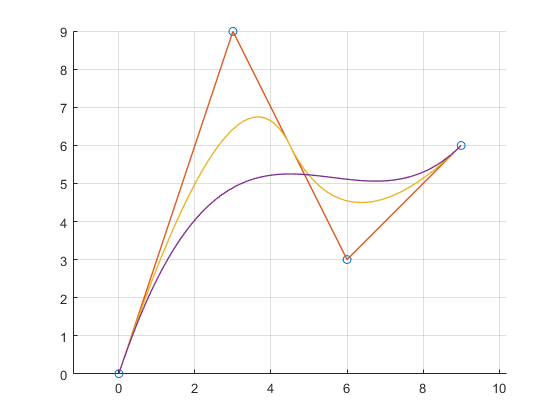

xv = [ 0 3 6 9];
yv = [ 0 9 3 6];

figure
clf
axis equal
hold on
scatter(xv,yv)
plot(xv,yv,'r:')
grid on
for k = 2:4
    drawBspline(k,xv,yv,'LineWidth',1);
end

### Example 2

Example 5-3 from [1] (pp 147-150).

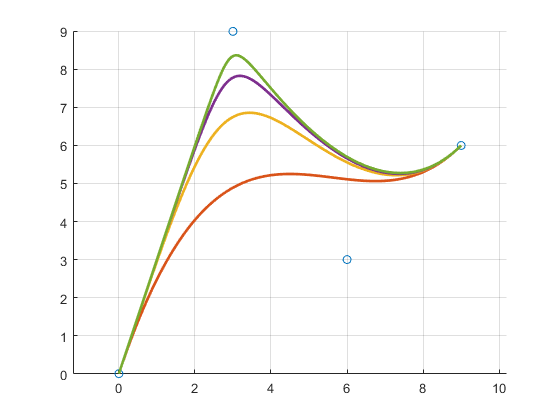

figure
clf
axis equal
hold on
xv = [ 0 3 6 9];
yv = [ 0 9 3 6];
scatter(xv,yv)
xv = [ 0 3 6 9];
yv = [ 0 9 3 6];
drawBspline(4,xv,yv,'LineWidth',2);
xv = [ 0 3 3 6 9];
yv = [ 0 9 9 3 6];
drawBspline(5,xv,yv,'LineWidth',2);
xv = [ 0 3 3 3 6 9];
yv = [ 0 9 9 9 3 6];
drawBspline(6,xv,yv,'LineWidth',2);
xv = [ 0 3 3 3 3 6 9];
yv = [ 0 9 9 9 9 3 6];
drawBspline(7,xv,yv,'LineWidth',2);
grid on

## References

[1]  Rogers, Adams, *Mathematical elements for Computer Graphics*, McGraw-Hill,1976